Limpar 

close all
clear
clc

# Lab 03 - Etapa 3

Para esta epa o calculo sera dividido em 2, analisando por partes ao invez de uma analise so para o circuito multi estagio, a escolha dessa forma é por facilitar os calculos e a reutilização das formulas ja utilizadas anteriormente.

## Circuito 1- Emissor Comum

** Calc Analise CC (DC)**

Figura 2- Circuito equivalente para analise CC

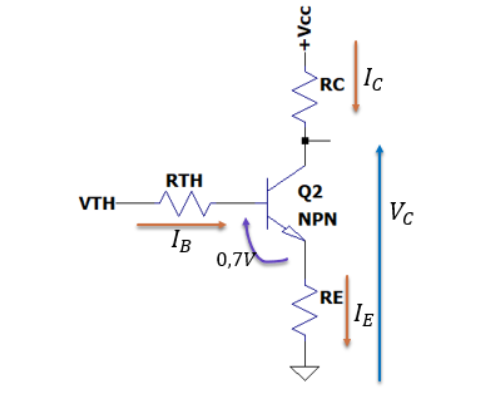

### Valores dos componentes:

ECR1 = 10e+3;%%Rth
ECR2 =2.2e+3;%%Rth
ECRE = 560;%% R2+R3
ECVcc = 12;%%Variavel de entrada
ECB = 290; % Beta para o calc
ECVbe = 0.7; 
ECVce = 5; %data sheet


### Equivalentes de TH

ECVth = (ECR2/(ECR1+ECR2))*ECVcc

ECVth = 2.1639

ECRth = ((1/ECR1)+(1/ECR2))^-1

ECRth = 1.8033e+03

### Correntes

ECIb = (ECVth-ECVbe)/(ECRth+ECRE*(ECB+1))

ECIb = 8.8851e-06

%%Ib = Vth/(Rth+RE*B+2*RE)%%Ib = (Vth-Vbe)/(Rth+RE*(B+1)) %%12e-6%%
ECIe = (ECB+1)*ECIb

ECIe = 0.0026

## **Calc Analise CA (AC)**

Figura 3- Circuito equivalente para analise CA

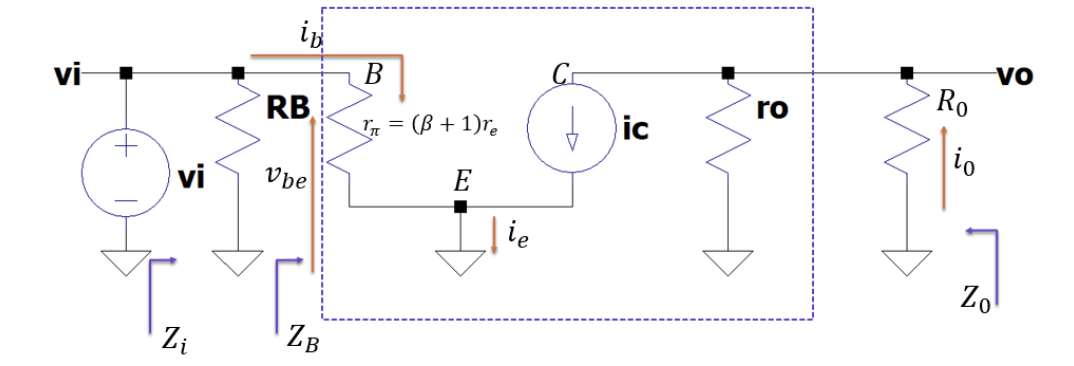

### Valores dos componentes 

*Obs.: todos os valores de componentes possuem a variavel com nome correspondente ao circuito apresentado na figura 1.


ECRC = 2.2e+3;%valor de entrada da figura 1
ECRB = ECRth; %calculado
ECR0 = ECRC%calculado R0

ECR0 = 2200

ECVT = 25e-3%%1.38e-23*((273+25)/1.6e-19)%%22e-3 Tensão termica dado no datasheet VT = (K*T)/q

ECVT = 0.0250

ECvi = 10e-3

ECvi = 0.0100

### calculo do re e rpi:

ECre = ECVT/ECIe

ECre = 9.6691

ECrpi = (ECB+1)*ECre

ECrpi = 2.8137e+03

**Calculo para CA**

ECib = ECvi/ECrpi

ECib = 3.5540e-06

ECic = ECB*ECib

ECic = 0.0010

ECie = ECic

ECie = 0.0010

ECv0 = ECic*ECR0

ECv0 = 2.2675

ECAv1 = ECv0/ECvi%ganho calculado usado 

ECAv1 = 226.7472

ECAv = -ECR0/ECre %ganho calculado por outro metodo para comparação

ECAv = -227.5291

Circuito 2-Arranjo darlington

 Figura 1- Circuito para analise da etapa 2.

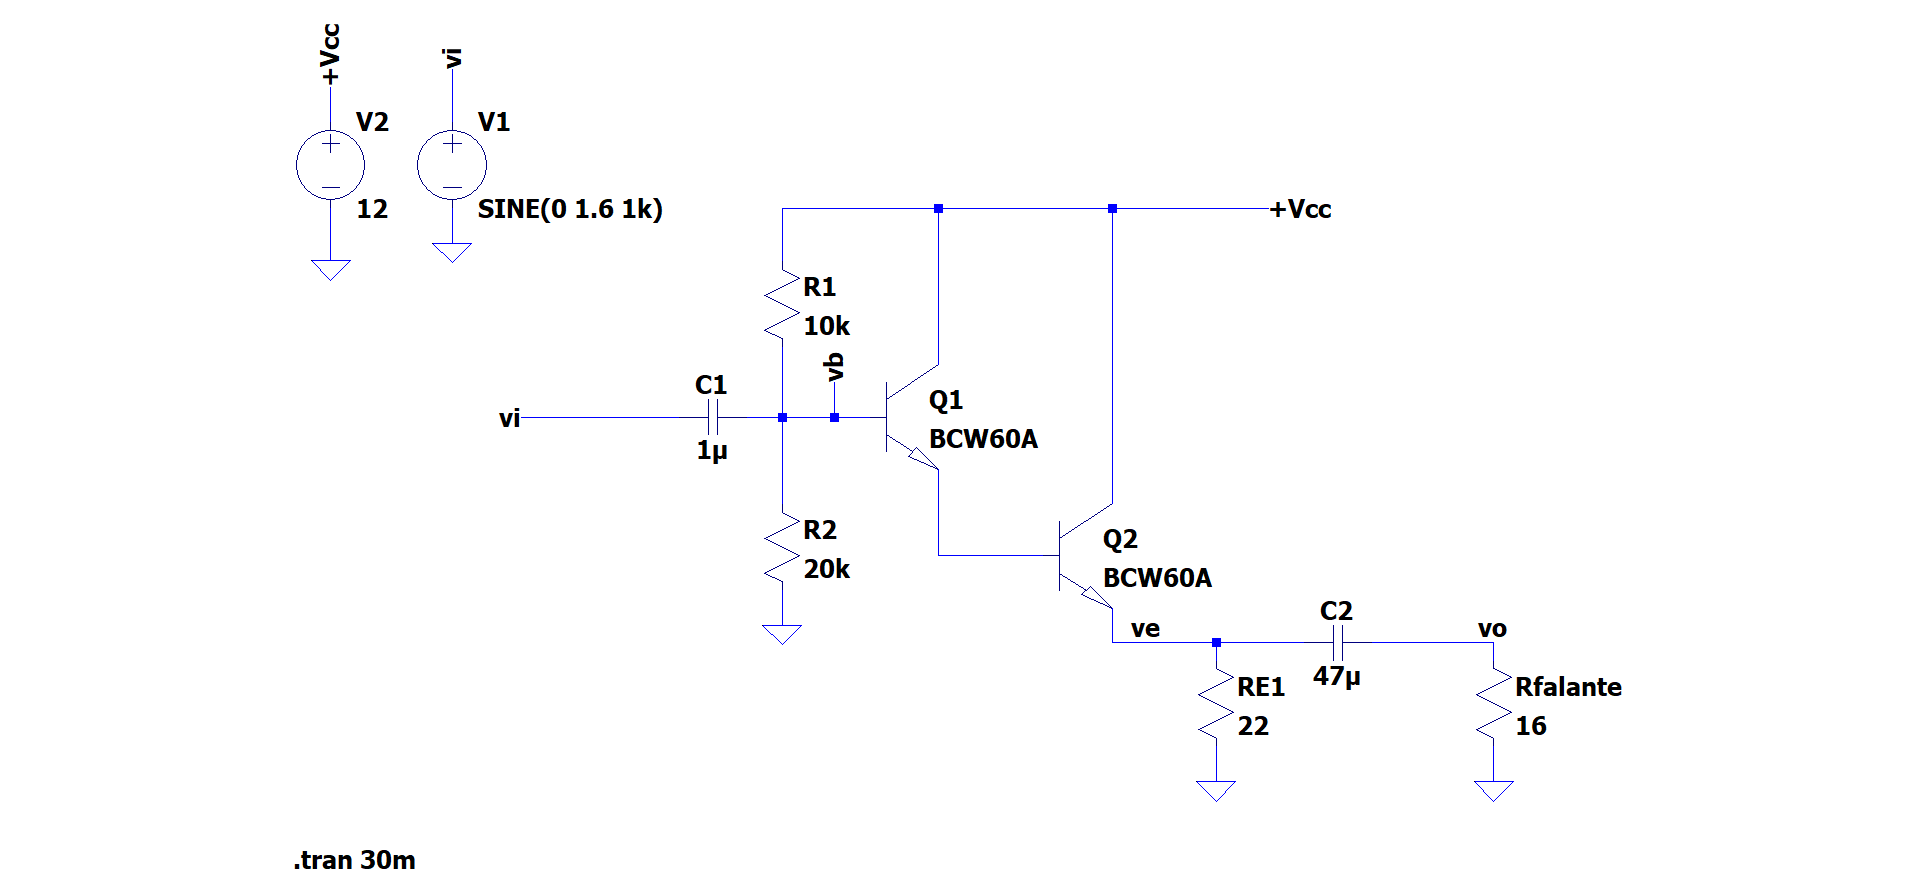

Condições iniciais da analise:

IC1 = IB2 = IE1     IC2 = B2*IB2             IC1=B1*IB1

Relação:

IB2 = IC1 = B1*IB1 e  IC2 = IE2=B2*B1*IB1

Valores de entrada:

B1 = 120;%%Beta do transistor 1
B2 = 120; %%Beta do transistor 2
B12 = B1*B2 %%Beta do circuito

B12 = 14400

vi = ECv0; %%valor de vi
Vcc = 12; %% Valor de vcc
R1 = 10e+3;
R2 = 20e+3;
RE = 22;
vbe = 0.7

vbe = 0.7000

vbe2 = vbe+vbe

vbe2 = 1.4000

RL = 16; %%Rfalante

Equivalente Thevenin:

Vth = (R2/(R1+R2))*Vcc

Vth = 8

Rth = ((1/R1)+(1/R2))^-1

Rth = 6.6667e+03

Calculos das correntes CC

IB1 = (Vth-vbe2)/(Rth+RE*B12)

IB1 = 2.0404e-05

IE2=B12*IB1

IE2 = 0.2938


IE1 = B1*IB1

IE1 = 0.0024

IB2 = IE1

IB2 = 0.0024

IC1 = IE1

IC1 = 0.0024

Valores para CA

VT = 25e-3;

R0  = ((1/RE)+(1/RL))^-1 

R0 = 9.2632

Calculos CA

re = VT/IE2

re = 0.0851


Av = RE/(RE+re)

Av = 0.9961

Ganho total do circuito

Avtotal = ECAv1*Av

Avtotal = 225.8736